`This simulation takes less than 1 minute on a typical computer, even a Raspberry Pi.`

`First we must ensure MatGemini is on the Matlab path:`

cwd = which('gemini3d');
addpath(fullfile(cwd, '..'))

`Pick an arbitrary output directory:`

outdir = '~/simulations/2dns_fang/';

`Simulation will fail if rerun, so get rid of existing output files first.`

outdir = gemini3d.fileio.expanduser(outdir);
filepat = outdir + "/*.h5";
if ~isempty(dir(filepat))
  delete(filepat)
end

`Now the simulation can be run.`

gemini3d.gemini_run(outdir, ...
  'config', fullfile(cwd, 'Examples/init/2dns_fang.nml'), ...
  'overwrite', false)

mpiexec -n 4 C:\Users\micha\code\gemini3d\build\gemini.bin.exe C:\Users\micha\simulations\2dns_fang\
           4 MPI processes detected 
C:\Users\micha\code\gemini3d\build\gemini.bin.exe Process:       3 /      3 at 20201014T030004.621 
C:\Users\micha\code\gemini3d\build\gemini.bin.exe Process:       2 /      3 at 20201014T030004.621 
C:\Users\micha\code\gemini3d\build\gemini.bin.exe Process:       0 /      3 at 20201014T030004.621 
C:\Users\micha\code\gemini3d\build\gemini.bin.exe Process:       1 /      3 at 20201014T030004.621 
 ******************** input config **************** 
simulation directory: C:\Users\micha\simulations\2dns_fang\ 
                            start year-month-day:    2013-02-20 
                                      start time:   18000.000 
                                        duration:     300.000 
                                    output every:      60.000 
gemini.f90: using input data files: 
C:\Users\micha\simulations\2dns_fang\/inputs/simsize.h5 


Finally, plot the output data.

sim grid dimensions: 48   1  20


Full or milestone input detected.
C:\Users\micha\simulations\2dns_fang\20130220_18000.000001.h5 => gemini3d.vis.plotfunctions.plot2D_cart


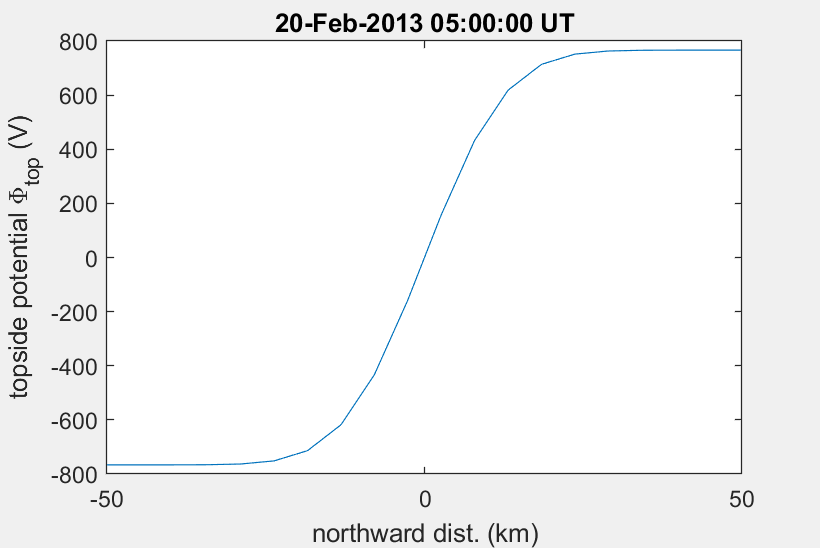

Full or milestone input detected.
C:\Users\micha\simulations\2dns_fang\20130220_18060.000000.h5 => gemini3d.vis.plotfunctions.plot2D_cart


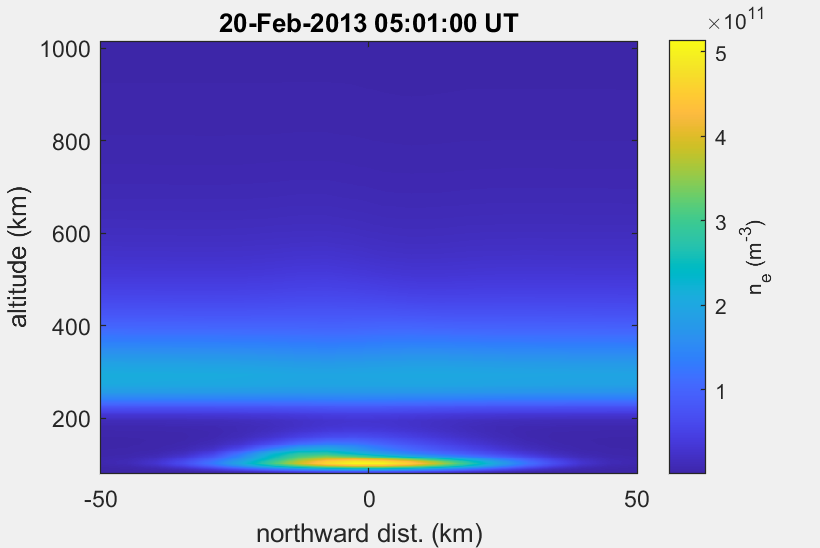

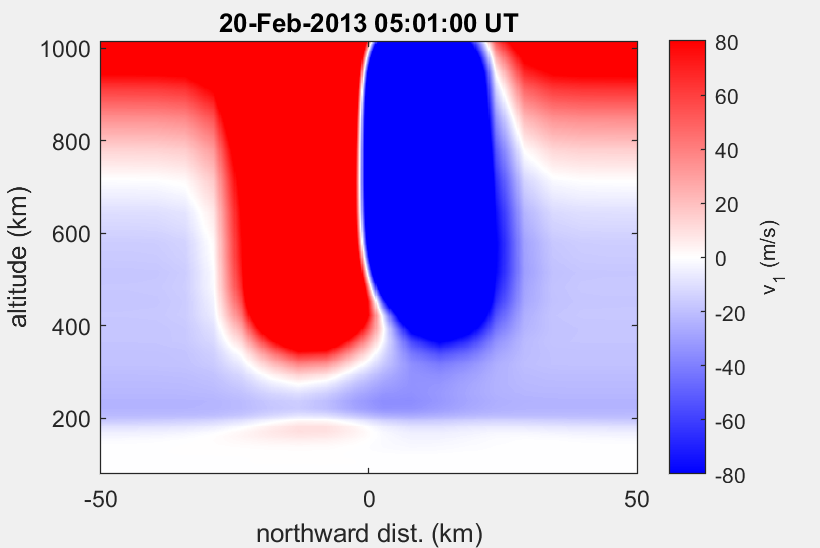

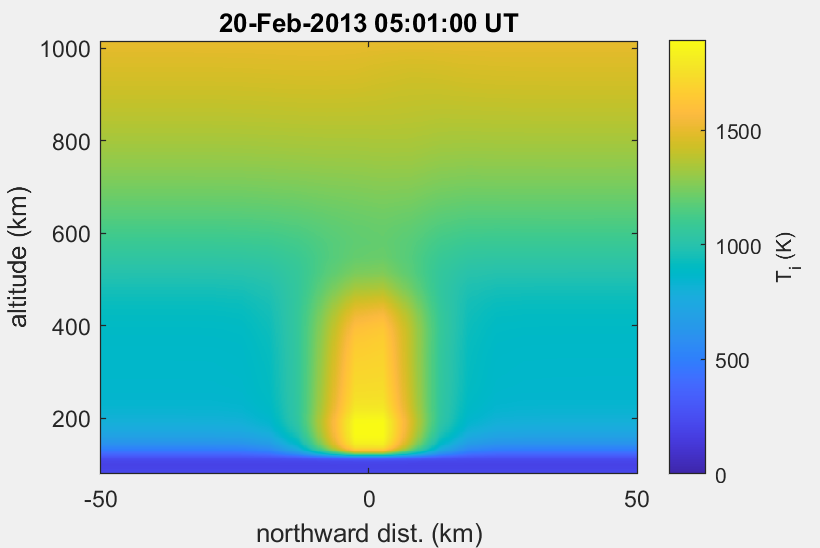

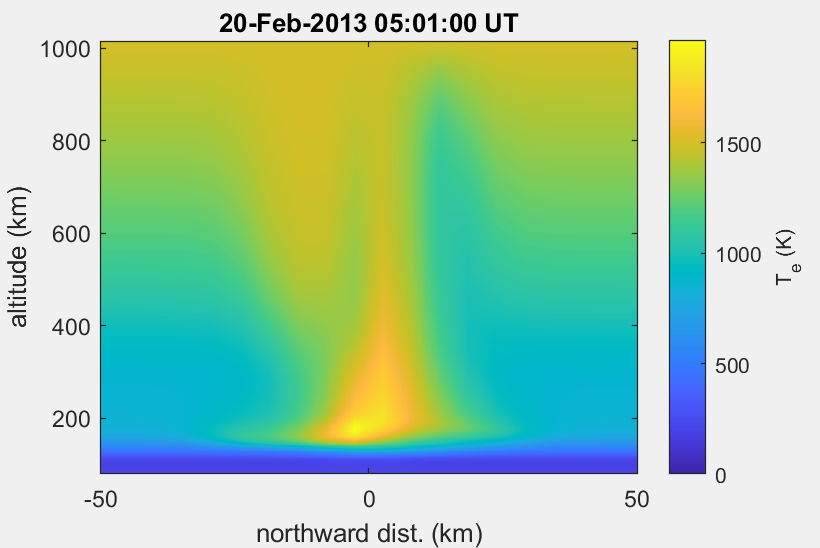

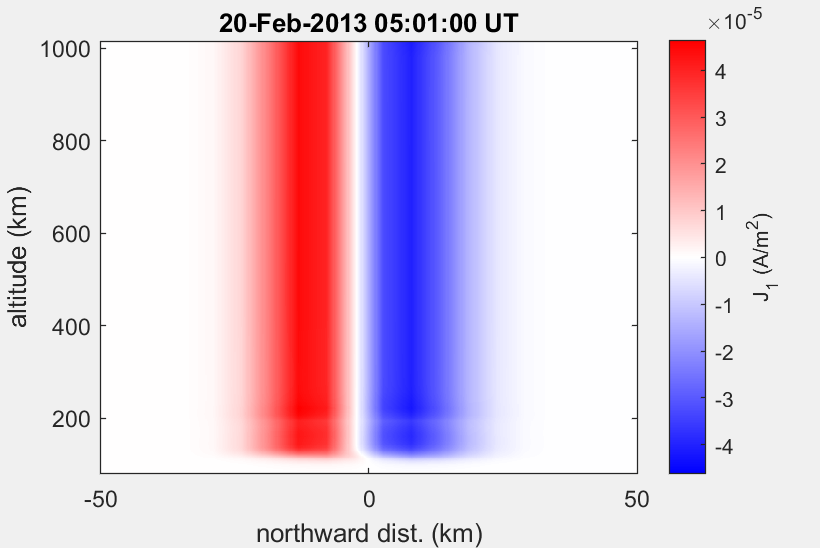

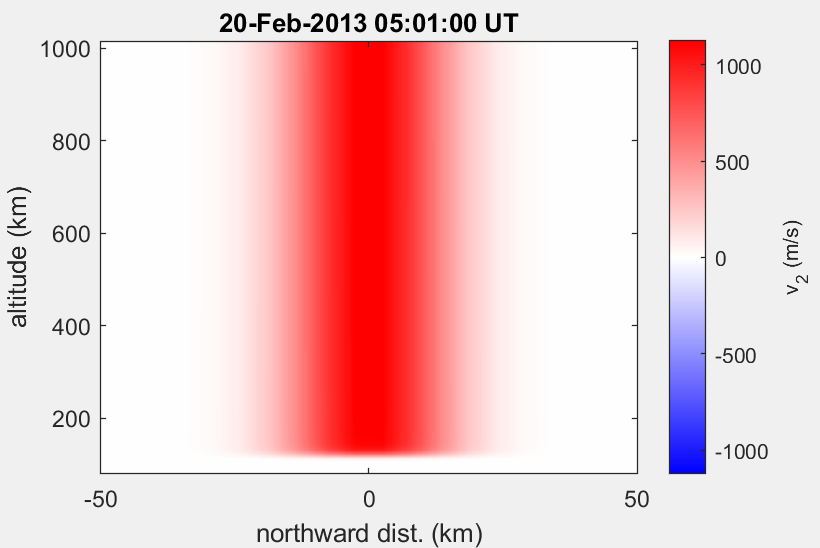

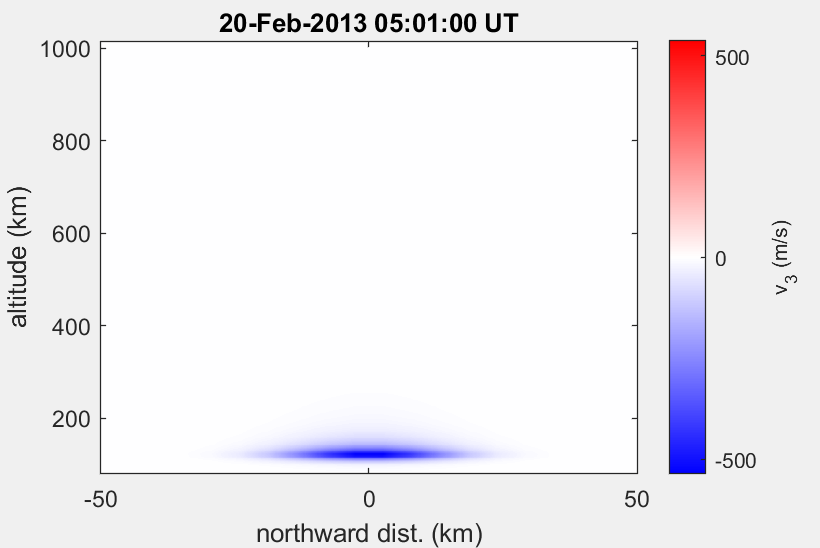

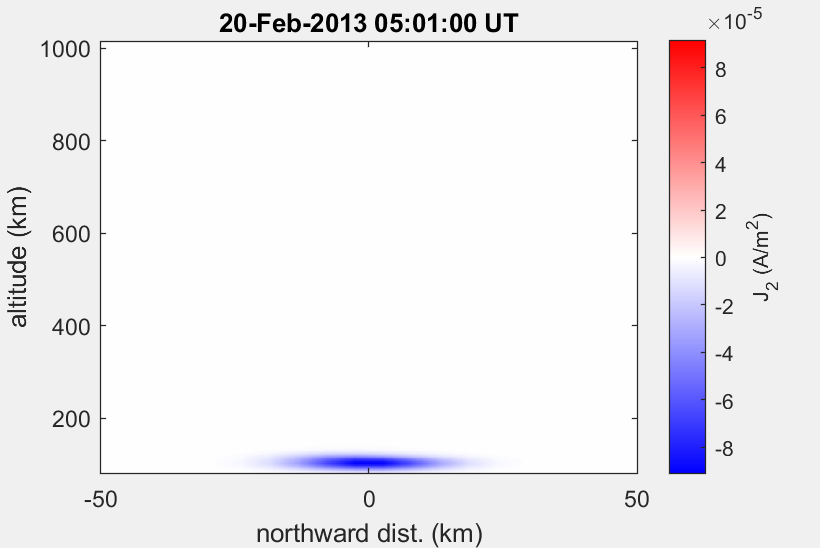

gemini3d.gemini_plot(outdir)